# Linearization of Differential Equations

Linearization is the process of taking the gradient of a nonlinear function with respect to all variables and creating a linear representation at that point. It is required for certain types of analysis such as stability analysis, solution with a Laplace transform, and to put the model into linear state-space form. Consider a nonlinear differential equation model that is derived from [**balance equations**](https://apmonitor.com/pdc/index.php/Main/PhysicsBasedModels) with input *u* and output *y*.

REMOVE LINKS


$$\frac{dy}{dt} = f(y,u)$$


The right hand side of the equation is linearized by a Taylor series expansion, using only the first two terms.


$$\frac{dy}{dt} = f(y,u) \approx f \left(\bar y, \bar u\right) + \frac{\partial f}{\partial y}\bigg|_{\bar y,\bar u} \left(y-\bar y\right) + \frac{\partial f}{\partial u}\bigg|_{\bar y,\bar u} \left(u-\bar u\right)$$


If the values of $\bar u
$ and $\bar y$ are chosen at steady state conditions then $f(\bar y, \bar u)=0$ because the derivative term ${dy}/{du}=0$ at steady state. To simplify the final linearized expression, deviation variables are defined as$ y' = y-\bar y$ and $u' = u - \bar u$. A deviation variable is a change from the nominal steady state conditions. The derivatives of the deviation variable is defined as ${dy'}/{dt} = {dy}/{dt}
$ because ${d\bar y}/{dt} = 0
$ in ${dy'}/{dt} = {d(y-\bar y)}/{dt} = {dy}/{dt} - {{d\bar y}/{dt}}$. 

BACKSLASH 

THIS LAST TERM SHOULD BE CANCELED

If there are additional variables such as a disturbance variable $d$ then it is added as another term in deviation variable form $d' = d - \bar d
$.


$$\frac{dy'}{dt} = \alpha y' + \beta u' + \gamma d'$$


The values of the constants $\alpha$, $\beta$, and $\gamma$ are the partial derivatives of $f(y,u,d)$ evaluated at steady state conditions.


$$\alpha = \frac{\partial f}{\partial y}\bigg|_{\bar y,\bar u,\bar d} \quad \quad \beta = \frac{\partial f}{\partial u}\bigg|_{\bar y,\bar u,\bar d} \quad \quad \gamma = \frac{\partial f}{\partial d}\bigg|_{\bar y,\bar u,\bar d}$$


### Example

**Part A**: Linearize the following differential equation with an input value of *u*=16.


$$\frac{dx}{dt} = -x^2 + \sqrt{u}$$


**Part B**: Determine the steady state value of *x* from the input value and simplify the linearized differential equation.

**Part C**: Simulate a doublet test with the nonlinear and linear models and comment on the suitability of the linear model to represent the original nonlinear equation solution.

**Part A Solution**: The equation is linearized by taking the partial derivative of the right hand side of the equation for both *x* and *u*.


$$\frac{\partial \left(-x^2 + \sqrt{u}\right)}{\partial x} = \alpha = -2 \, x$$



$$\frac{\partial \left(-x^2 + \sqrt{u}\right)}{\partial u} = \beta = \frac{1}{2} \frac{1}{\sqrt{u}}
$$


The linearized differential equation that approximates $\frac{dx}{dt}=f(x,u)$ is the following:


$$\frac{dx}{dt} = f \left(x_{ss}, u_{ss}\right) + \frac{\partial f}{\partial x}\bigg|_{x_{ss},u_{ss}} \left(x-x_{ss}\right) + \frac{\partial f}{\partial u}\bigg|_{x_{ss},u_{ss}} \left(u-u_{ss}\right)

$$


Substituting in the partial derivatives results in the following differential equation:


$$\frac{dx}{dt} = 0 + \left(-2 x_{ss}\right) \left(x-x_{ss}\right) + \left(\frac{1}{2} \frac{1}{\sqrt{u_{ss}}}\right) \left(u-u_{ss}\right)
$$


I DONT THINK WE CAN KNOW f(xss, uss) = 0 YET SINCE WE HAVE NOT YET SOLVED FOR XSS

This is further simplified by defining new deviation variables as $x' = x - x_{ss}
$ and $u' = u - u_{ss}
$.


$$\frac{dx'}{dt} = \alpha x' + \beta u'
$$


**Part B Solution**: The steady state values are determined by setting $\frac{dx}{dt}=0$ and solving for *x*.


$$0 = -x_{ss}^2 + \sqrt{u_{ss}}$$



$$x_{ss}^2 = \sqrt{16}$$



$$x_{ss} = 2$$


At steady state conditions, $\frac{dx}{dt}=0$ so $ f (x_{ss}, u_{ss})=0$ as well. Plugging in numeric values gives the simplified linear differential equation:


$$\frac{dx}{dt} = -4 \left(x-2\right) + \frac{1}{8} \left(u-16\right)$$


The partial derivatives can also be obtained from MATLAB, either symbolically or else numerically.

% analytic solution with MATLAB
% define symbols
syms x u
% define equation
dxdt = -x^2 + sqrt(u)

$$dxdt = \sqrt{u}-x^{2}$$


%Calculate and print 
disp("Partial of dxdt by x")

Partial of dxdt by x


pd_x = diff(dxdt, x)

$$pd\_x = -2\,x$$

disp("Partial of dxdt by u")

Partial of dxdt by u


pd_u = diff(dxdt, u)

$$pd\_u = \frac{1}{2\,\sqrt{u}}$$

% numeric solution with MATLAB
u = 16;
x = 2;

disp("Approximate Partial Derivatives")

Approximate Partial Derivatives


subs(pd_x) 

$$ans = -4$$

subs(pd_u)

$$ans = \frac{1}{8}$$


disp("Exact Partial Derivatives")

Exact Partial Derivatives


disp(-2.0*x)      % exact d(f(x,u))/dx

    -4



disp(0.5/sqrt(u)) % exact d(f(x,u))/dufunction dxdt = pd_x(x, u)

    0.1250



The nonlinear function for $\frac{dx}{dt}$ can also be visualized with a 3D contour map. The choice of steady state conditions $x_{ss}$ and $u_{ss}$ produces a planar linear model that represents the nonlinear model only at a certain point. The linear model can deviate from the nonlinear model if used further away from the conditions at which the linear model is derived.

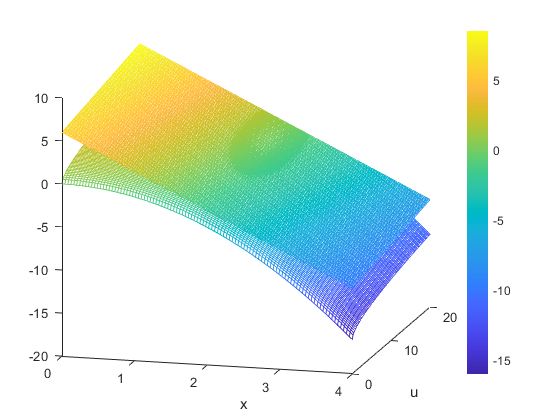

figure(1);

% Make data
x = linspace(0, 4, 100);
u = linspace(0, 20, 100);
[X, U] = meshgrid(x, u);
DXDT = -X.^2 + sqrt(U);
LIN = -4*(X-2) + (U-16)/8;

% Plot Surfaces
hold on
mesh(X, U, LIN)
mesh( X, U, DXDT )
view(15, 15) % orients graph properly
colorbar

% Add labels
hold off
ylabel('u')
xlabel('x')

**Part C Solution**: The final step is to simulate a doublet test with the nonlinear and linear models.

*Small step changes (+/-1)*: Small step changes in *u* lead to nearly identical responses for the linear and nonlinear solutions. The linearized model is *locally* accurate. (m = 1 in the code below)

*Large step changes (+/-8)*: As the magnitude of the doublet steps increase, the linear model deviates further from the original nonlinear equation solution. (m = 8 in the code below)

clear
clc

% Steady state conditions
x_ss = 2.0

x_ss = 2

u_ss = 16.0

u_ss = 16


% Inital conditions
z0 = [x_ss, x_ss]

z0 =      2     2


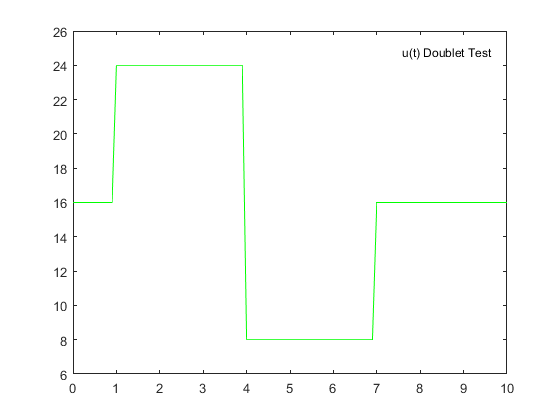


% Final time
tf = 10;

% Number of time points
n = tf*10 + 1;

% Time points
t = linspace(0,tf,n);
% save time for plotting
torig = t;

% Step input
u = ones(1,n)*u_ss;
% Magnitude of the step
m = 8;  
% change up m at time = 1.0
u(11:40) = u_ss + m;
% change down 2*m at time = 4.0
u(41:71) = u_ss - m;
% change up at time = 7.0
u(71:length(u)) = u_ss;

% Container for solution and record initial conditions
x1all = [z0(1)];
x2all = [z0(2)];
tall = [0];

% Solve ODE
for i = 1:length(u)
    [t, z] = ode45(@(t, z) model(t, z, u(i)), [0, 0.1], z0);
    % Store solution
    x1all = [x1all; z(:, 1)];
    x2all = [x2all; z(:, 2)];
    tall = [tall; t + i/10];
    % Set initial conditions
    z0 = [z(41,1), z(41,2)];
end

% Plot results
figure(2);
clf
p3 = plot(torig, u, 'g');
legend([p3], {'u(t) Doublet Test'})
ylim([(min(u)-2),(max(u)+2)])

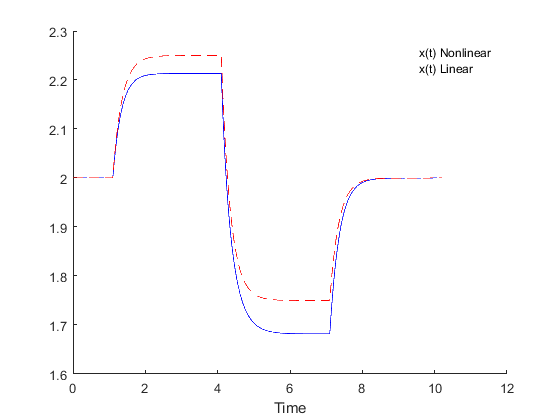


figure(3);
clf
hold on
p1 = plot(tall, x1all, 'b');
p2 = plot(tall, x2all, 'r--');
% plot((0:101)/10, z0all)
legend([p1 p2],{'x(t) Nonlinear', 'x(t) Linear'})
xlabel('Time')

function z = model(t, z, u)
%funtion that returns dz/dt
    x1 = z(1);
    x2 = z(2);
    dx1dt = -x1^2 + sqrt(u);
    dx2dt = -4*(x2 - 2) + (u -16)/8;
    dzdt = [dx1dt, dx2dt]';
    z = dzdt;
end